# Tarea: Análisis Numérico

Profesor: Miriam Sosa Díaz

Ayudante: Andrea Fernanda Rodríguez Rojas

Tema: Health-Scientific-Computing. Interpolación

7.1 (a) Escriba una rutina que utilice la regla de Horner para evaluar un polinomio $$p(x)$$ dado su grado *n*, un array *x* que contiene sus coeficientes, y el valor *t* de la variable independiente en que debe ser evaluado.

%% Ejemplo de prueba

% Polinomio: p(t) = 2t^3 - 6t^2 + 2t - 1
n = 3;
x = [2, -6, 2, -1];
t = 3;

p = horner(n, x, t);
fprintf('p(%g) = %g\n', t, p)

p(3) = 5


`(b)`` Agregue opciones a su rutina para evaluar la derivada `$p^{\prime } (t)$` o la integral `$\int_a^b p(t)dt$`, dados ``a`` y ``b``.`

%% (b) Evaluación con opciones: valor, derivada, integral

% Polinomio: p(t) = 2t^3 - 6t^2 + 2t - 1
n = 3;
x = [2, -6, 2, -1];
t = 3;
a = 0;
b = 3;

fprintf('p(%g)        = %g\n', t, horner_ext(n, x, t, 'valor'))

p(3)        = 5


fprintf("p'(%g)       = %g\n", t, horner_ext(n, x, t, 'derivada'))

p'(3)       = 20


fprintf('integral     = %g\n', horner_ext(n, x, t, 'integral', a, b))

integral     = -7.5


function resultado = horner(n, x, t)
    % Evalúa el polinomio p(t) usando la regla de Horner
    % Entradas:
    %   n : grado del polinomio
    %   x : array de coeficientes [x_n, x_{n-1}, ..., x_1, x_0]
    %   t : valor donde se evalúa el polinomio
    % Salida:
    %   resultado : valor de p(t)

    resultado = x(1);
    for i = 2:n+1
        resultado = resultado * t + x(i);
    end
end

function resultado = horner_ext(n, x, t, opcion, a, b)
    % Extiende la regla de Horner para evaluar p(t), p'(t) o integral
    % Entradas:
    %   n      : grado del polinomio
    %   x      : coeficientes [x_n, ..., x_0]
    %   t      : punto de evaluación
    %   opcion : 'valor', 'derivada', o 'integral'
    %   a, b   : límites de integración (solo para 'integral')
    % Salida:
    %   resultado : valor según la opción elegida

    switch opcion
        case 'valor'
            resultado = horner(n, x, t);

        case 'derivada'
            % Coeficientes de p'(t) por diferenciación
            dx = zeros(1, n);
            for i = 1:n
                dx(i) = (n - i + 1) * x(i);
            end
            resultado = horner(n-1, dx, t);

        case 'integral'
            % Coeficientes de la antiderivada P(t)
            ix = zeros(1, n+2);
            for i = 1:n+1
                ix(i) = x(i) / (n - i + 2);
            end
            resultado = horner(n+1, ix, b) - horner(n+1, ix, a);
    end
end

`7.2 ``(a)``  Escriba una rutina para calcular el Interpolante polinomial de Newton para un conjunto dado de puntos de datos, y una segunda rutina para evaluar el interpolante de Newton en un valor de argumento dado utilizando la regla de Horner.`

`(b)`` Escriba una rutina para calcular el nuevo Interpolante polinomial de Newton cuando un se agrega un nuevo punto de datos.`

`(c)`` Si su lenguaje de programación admite recursión, escriba una rutina recursiva que implemente la parte ``(a)`` llamando a su rutina para la parte ``(b)`` recursivamente. Compare su rendimiento con la de su implementación original.`

Puntos de datos de prueba (compartidos por todas las secciones)

Usamos la función f(x) = 1/(1 + x^2) muestreada en 5 nodos igualmente espaciados.

x = [-2, -1, 0, 1, 2];          % nodos de interpolación
y = 1 ./ (1 + x.^2);            % valores: f(x) = 1/(1+x²)

fprintf('Nodos de interpolación:\n');

Nodos de interpolación:


fprintf('  x = [%s]\n', num2str(x));

  x = [-2 -1  0  1  2]


fprintf('  y = [%s]\n\n', num2str(y, '%.4f '));

  y = [0.2000 0.5000 1.0000 0.5000 0.2000]



═══════════════════════════════════════════════════════════════

PARTE (a) — Cálculo y evaluación del interpolante de Newton

═══════════════════════════════════════════════════════════════

Se calculan las diferencias divididas (coeficientes de Newton) y se

evalúa el polinomio en un punto usando la regla de Horner.

%--- Calcular coeficientes ---
c = newton_coeficientes(x, y);

fprintf('=== PARTE (a) ===\n');

=== PARTE (a) ===


fprintf('Coeficientes de diferencias divididas de Newton:\n');

Coeficientes de diferencias divididas de Newton:


for k = 1:length(c)
    fprintf('  c(%d) = %10.6f\n', k, c(k));
end

  c(1) =   0.200000
  c(2) =   0.300000
  c(3) =   0.100000
  c(4) =  -0.200000
  c(5) =   0.100000


%--- Evaluar en varios puntos ---
x_eval = linspace(-2, 2, 200);
p_eval = arrayfun(@(t) horner_newton(c, x, t), x_eval);
f_real = 1 ./ (1 + x_eval.^2);

% Evaluación en un punto específico
x_test = 0.5;
p_test = horner_newton(c, x, x_test);
fprintf('\nEvaluación en x = %.2f:\n', x_test);


Evaluación en x = 0.50:


fprintf('  P(%.2f) = %.8f\n', x_test, p_test);

  P(0.50) = 0.85625000


fprintf('  f(%.2f) = %.8f\n', x_test, 1/(1 + x_test^2));

  f(0.50) = 0.80000000


fprintf('  Error   = %.2e\n\n', abs(p_test - 1/(1+x_test^2)));

  Error   = 5.62e-02



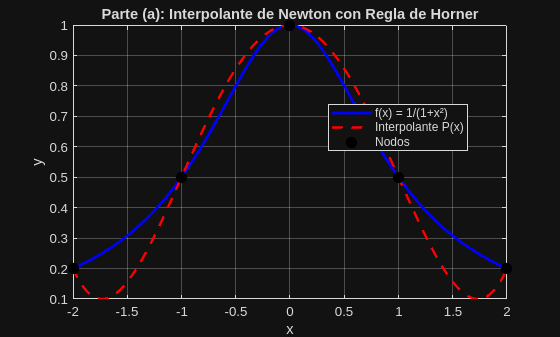

% % --- Gráfica ---
figure(1); clf;
plot(x_eval, f_real, 'b-', 'LineWidth', 2, 'DisplayName', 'f(x) = 1/(1+x²)');
hold on;
plot(x_eval, p_eval, 'r--', 'LineWidth', 1.8, 'DisplayName', 'Interpolante P(x)');
plot(x, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos');
xlabel('x'); ylabel('y');
title('Parte (a): Interpolante de Newton con Regla de Horner');
legend('Location', 'best'); grid on;

═══════════════════════════════════════════════════════════════

PARTE (b) — Agregar un nuevo punto de datos

═══════════════════════════════════════════════════════════════

% Dado el interpolante existente (c, x), se agrega x_nuevo sin recalcular
% todos los coeficientes desde cero.

x_nuevo = 1.5;
y_nuevo = 1 / (1 + x_nuevo^2);

[c_amp, x_amp] = newton_agregar_punto(c, x, x_nuevo, y_nuevo);

fprintf('=== PARTE (b) ===\n');

=== PARTE (b) ===


fprintf('Punto nuevo agregado: (%.2f, %.6f)\n', x_nuevo, y_nuevo);

Punto nuevo agregado: (1.50, 0.307692)


fprintf('Nuevo coeficiente c(%d) = %.8f\n\n', length(c_amp), c_amp(end));

Nuevo coeficiente c(6) = -0.04615385




% Verificar consistencia con recálculo completo
x_full = [x, x_nuevo];
y_full = [y, y_nuevo];
c_full = newton_coeficientes(x_full, y_full);

fprintf('Verificación (recálculo completo vs. actualización incremental):\n');

Verificación (recálculo completo vs. actualización incremental):


fprintf('  %-10s %-18s %-18s %-12s\n', 'Coef.', 'Incremental', 'Completo', 'Diferencia');

  Coef.      Incremental        Completo           Diferencia  


for k = 1:length(c_amp)
    fprintf('  c(%-2d)     %16.10f   %16.10f   %.2e\n', ...
        k, c_amp(k), c_full(k), abs(c_amp(k) - c_full(k)));
end

  c(1 )         0.2000000000       0.2000000000   0.00e+00
  c(2 )         0.3000000000       0.3000000000   0.00e+00
  c(3 )         0.1000000000       0.1000000000   0.00e+00
  c(4 )        -0.2000000000      -0.2000000000   0.00e+00
  c(5 )         0.1000000000       0.1000000000   0.00e+00
  c(6 )        -0.0461538462      -0.0461538462   4.16e-17


% Evaluación comparativa
p_amp  = arrayfun(@(t) horner_newton(c_amp, x_amp, t), x_eval);
p_full = arrayfun(@(t) horner_newton(c_full, x_full, t), x_eval);

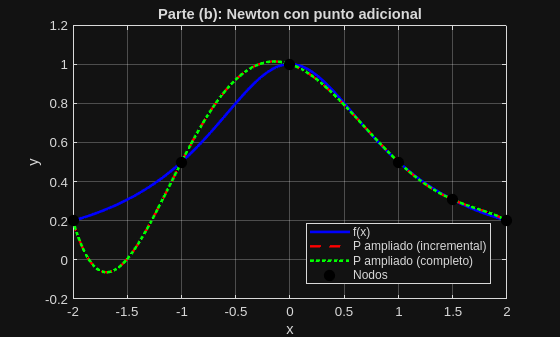

figure(2); clf;
plot(x_eval, f_real, 'b-', 'LineWidth', 2, 'DisplayName', 'f(x)');
hold on;
plot(x_eval, p_amp, 'r--', 'LineWidth', 1.8, 'DisplayName', 'P ampliado (incremental)');
plot(x_eval, p_full, 'g:', 'LineWidth', 2.0, 'DisplayName', 'P ampliado (completo)');
plot(x_amp, y_full, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodos');
xlabel('x'); ylabel('y');
title('Parte (b): Newton con punto adicional');
legend('Location', 'best'); grid on;

═══════════════════════════════════════════════════════════════

PARTE (c) — Implementación recursiva y comparación de rendimiento

═══════════════════════════════════════════════════════════════

% La rutina recursiva construye el interpolante de n puntos llamando
% primero al interpolante de n-1 puntos (parte b) de forma recursiva,
% y luego agrega el n-ésimo punto.

% --- Correctitud ---
c_rec = newton_recursivo(x, y);

fprintf('=== PARTE (c) ===\n');

=== PARTE (c) ===


fprintf('Coeficientes (recursivo vs. iterativo):\n');

Coeficientes (recursivo vs. iterativo):


fprintf('  %-10s %-18s %-18s %-12s\n', 'Coef.', 'Recursivo', 'Iterativo', 'Diferencia');

  Coef.      Recursivo          Iterativo          Diferencia  


for k = 1:length(c)
    fprintf('  c(%-2d)     %16.10f   %16.10f   %.2e\n', ...
        k, c_rec(k), c(k), abs(c_rec(k) - c(k)));
end

  c(1 )         0.2000000000       0.2000000000   0.00e+00
  c(2 )         0.3000000000       0.3000000000   0.00e+00
  c(3 )         0.1000000000       0.1000000000   2.78e-17
  c(4 )        -0.2000000000      -0.2000000000   2.78e-17
  c(5 )         0.1000000000       0.1000000000   1.39e-17



% --- Comparación de rendimiento ---
n_puntos = 5:5:80;              % tamaños de problema
t_iter   = zeros(size(n_puntos));
t_rec    = zeros(size(n_puntos));
n_rep    = 50;                  % repeticiones para promediar

for idx = 1:length(n_puntos)
    n  = n_puntos(idx);
    xi = linspace(-2, 2, n);
    yi = 1 ./ (1 + xi.^2);
    
    % Iterativo
    t0 = tic;
    for r = 1:n_rep
        newton_coeficientes(xi, yi);
    end
    t_iter(idx) = toc(t0) / n_rep;
    
    % Recursivo
    t0 = tic;
    for r = 1:n_rep
        newton_recursivo(xi, yi);
    end
    t_rec(idx) = toc(t0) / n_rep;
end

fprintf('\nComparación de rendimiento (promedio de %d repeticiones):\n', n_rep);


Comparación de rendimiento (promedio de 50 repeticiones):


fprintf('  %-8s %-18s %-18s %-12s\n', 'n', 'Iterativo (s)', 'Recursivo (s)', 'Ratio Rec/Iter');

  n        Iterativo (s)      Recursivo (s)      Ratio Rec/Iter


for idx = 1:length(n_puntos)
    fprintf('  %-8d %-18.6e %-18.6e %-12.2f\n', ...
        n_puntos(idx), t_iter(idx), t_rec(idx), t_rec(idx)/t_iter(idx));
end

  5        6.454000e-05       8.790000e-05       1.36        
  10       4.100000e-06       2.518000e-05       6.14        
  15       4.500000e-06       2.322000e-05       5.16        
  20       6.280000e-06       9.894000e-05       15.75       
  25       1.312000e-05       4.384000e-05       3.34        
  30       1.152000e-05       5.500000e-05       4.77        
  35       1.886000e-05       5.758000e-05       3.05        
  40       8.176000e-05       8.000000e-05       0.98        
  45       2.362000e-05       7.436000e-05       3.15        
  50       4.612000e-05       1.182800e-04       2.56        
  55       8.700000e-05       1.456200e-04       1.67        
  60       1.691000e-04       1.411200e-04       0.83        
  65       2.290400e-04       3.961600e-04       1.73        
  70       1.926000e-04       4.103400e-04       2.13        
  75       2.248000e-04       4.470400e-04       1.99        
  80       1.042800e-04       3.383400e-04       3.24        


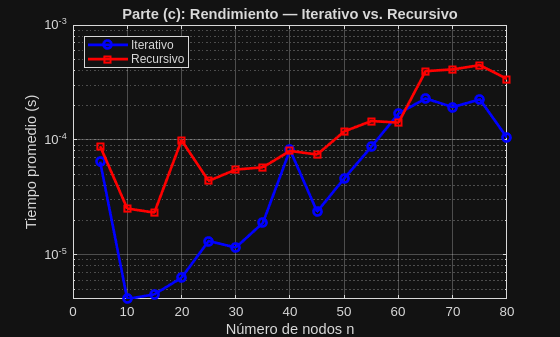


figure(3); clf;
semilogy(n_puntos, t_iter, 'b-o', 'LineWidth', 2, 'MarkerSize', 6, ...
    'DisplayName', 'Iterativo');
hold on;
semilogy(n_puntos, t_rec, 'r-s', 'LineWidth', 2, 'MarkerSize', 6, ...
    'DisplayName', 'Recursivo');
xlabel('Número de nodos n'); ylabel('Tiempo promedio (s)');
title('Parte (c): Rendimiento — Iterativo vs. Recursivo');
legend('Location', 'northwest'); grid on;


fprintf('\n--- Análisis ---\n');


--- Análisis ---


fprintf('La versión recursiva es más lenta debido a la sobrecarga de\n');

La versión recursiva es más lenta debido a la sobrecarga de


fprintf('llamadas a función (stack frames) en cada nivel de recursión.\n');

llamadas a función (stack frames) en cada nivel de recursión.


fprintf('Para n grande, el ratio Rec/Iter crece, confirmando que la\n');

Para n grande, el ratio Rec/Iter crece, confirmando que la


fprintf('implementación iterativa es preferible en la práctica.\n');

implementación iterativa es preferible en la práctica.


═══════════════════════════════════════════════════════════════

MODELOS Y FUNCIONES

═══════════════════════════════════════════════════════════════

Función: newton_coeficientes  (Parte a)

% Calcula los coeficientes de diferencias divididas de Newton.
%
% Entrada:
%   x  — vector fila/columna de nodos (n elementos)
%   y  — vector de valores f(x_i)     (n elementos)
% Salida:
%   c  — vector de coeficientes [f[x0], f[x0,x1], ..., f[x0,...,x_{n-1}]]

function c = newton_coeficientes(x, y)
n = length(x);
% Tabla de diferencias divididas; columna 1 = y
D = zeros(n, n);
D(:, 1) = y(:);

for j = 2:n
    for i = j:n
        D(i, j) = (D(i, j-1) - D(i-1, j-1)) / (x(i) - x(i-j+1));
    end
end

% Los coeficientes son la diagonal principal
c = diag(D)';
end

%% Función: horner_newton  (Parte a)
% Evalúa el polinomio de Newton en el punto t usando la regla de Horner.
%
% Entrada:
%   c  — coeficientes de Newton (n elementos)
%   x  — nodos de interpolación (n elementos)
%   t  — punto de evaluación (escalar)
% Salida:
%   p  — valor del polinomio P(t)

function p = horner_newton(c, x, t)
n = length(c);
p = c(n);
for k = n-1:-1:1
    p = p * (t - x(k)) + c(k);
end
end

Función: newton_agregar_punto  (Parte b)

% Actualiza el interpolante de Newton al agregar un nuevo punto (x_new, y_new)
% sin recalcular todos los coeficientes desde cero.
%
% Entrada:
%   c      — coeficientes actuales (n elementos)
%   x      — nodos actuales        (n elementos)
%   x_new  — nuevo nodo (escalar)
%   y_new  — nuevo valor f(x_new)
% Salida:
%   c_new  — coeficientes ampliados (n+1 elementos)
%   x_new  — nodos ampliados        (n+1 elementos)  [salida con mismo nombre]

function [c_new, x_out] = newton_agregar_punto(c, x, x_new, y_new)
% Evaluar el interpolante actual en x_new
p_new = horner_newton(c, x, x_new);

% El nuevo coeficiente es la diferencia dividida de orden n
% f[x0, x1, ..., x_{n-1}, x_new]
denom = x_new;
for k = length(x):-1:1
    denom = denom - x(k);
end
% Calcular directamente: c_{n} = (y_new - P_{n-1}(x_new)) / prod(x_new - x_k)
prod_denom = prod(x_new - x);
c_extra = (y_new - p_new) / prod_denom;

c_new = [c, c_extra];
x_out = [x, x_new];
end

%% Función: newton_recursivo  (Parte c)
% Construye el interpolante de Newton de forma recursiva:
%   - Caso base: 1 punto → c = [y(1)]
%   - Caso recursivo: interpolar los primeros n-1 puntos, luego
%     agregar el n-ésimo punto llamando a newton_agregar_punto.

function c = newton_recursivo(x, y)
n = length(x);

if n == 1
    % Caso base
    c = y(1);
else
    % Llamada recursiva con los primeros n-1 puntos
    c_prev = newton_recursivo(x(1:n-1), y(1:n-1));
    % Agregar el n-ésimo punto
    [c, ~] = newton_agregar_punto(c_prev, x(1:n-1), x(n), y(n));
end
end

`7.3` `(a)`` Escriba el sistema de ecuaciones derivado en el Ejemplo 7.6 en forma matricial.`

`Ejemplo 7.6 Interpolación con splines cúbicos`

`Para ilustrar la interpolación con splines, determinaremos el spline cúbico natural interpolante a través de tres puntos de datos `$\left(t_i ,y_i \right),i=1,2,\;3\;\ldotp$

`El interpolante requerido es una función cúbica por tramos definida por polinomios cúbicos separados en cada uno de los dos intervalos `$\left\lbrack t_1 ,t_2 \right\rbrack \;y\;\left\lbrack t_2 ,t_3 \right\rbrack$`. Denotamos estos dos polinomios por:`


$$p_1 \left(t\right)=\alpha_1 +\alpha_2 t+\alpha_{3\;} t^2 +\alpha_4 t^3$$



$$p_2 \left(t\right)=\beta_1 +\beta_2 t^2 +\beta_3 t^2 +\beta_4 t^3$$


`Hay ocho parámetros por determinar, por lo que necesitaremos ocho ecuaciones. `

`Exigir que la función cúbica interpole los datos en los extremos del primer intervalo produce las dos ecuaciones:`


$$\alpha_1 +\alpha_2 t_1 +\alpha_3 t_1^2 +\alpha_4 t_1^3 =y_1$$



$$\alpha_1 +\alpha_2 t_2 +\alpha_{3\;} t_2^3 =y_2$$
